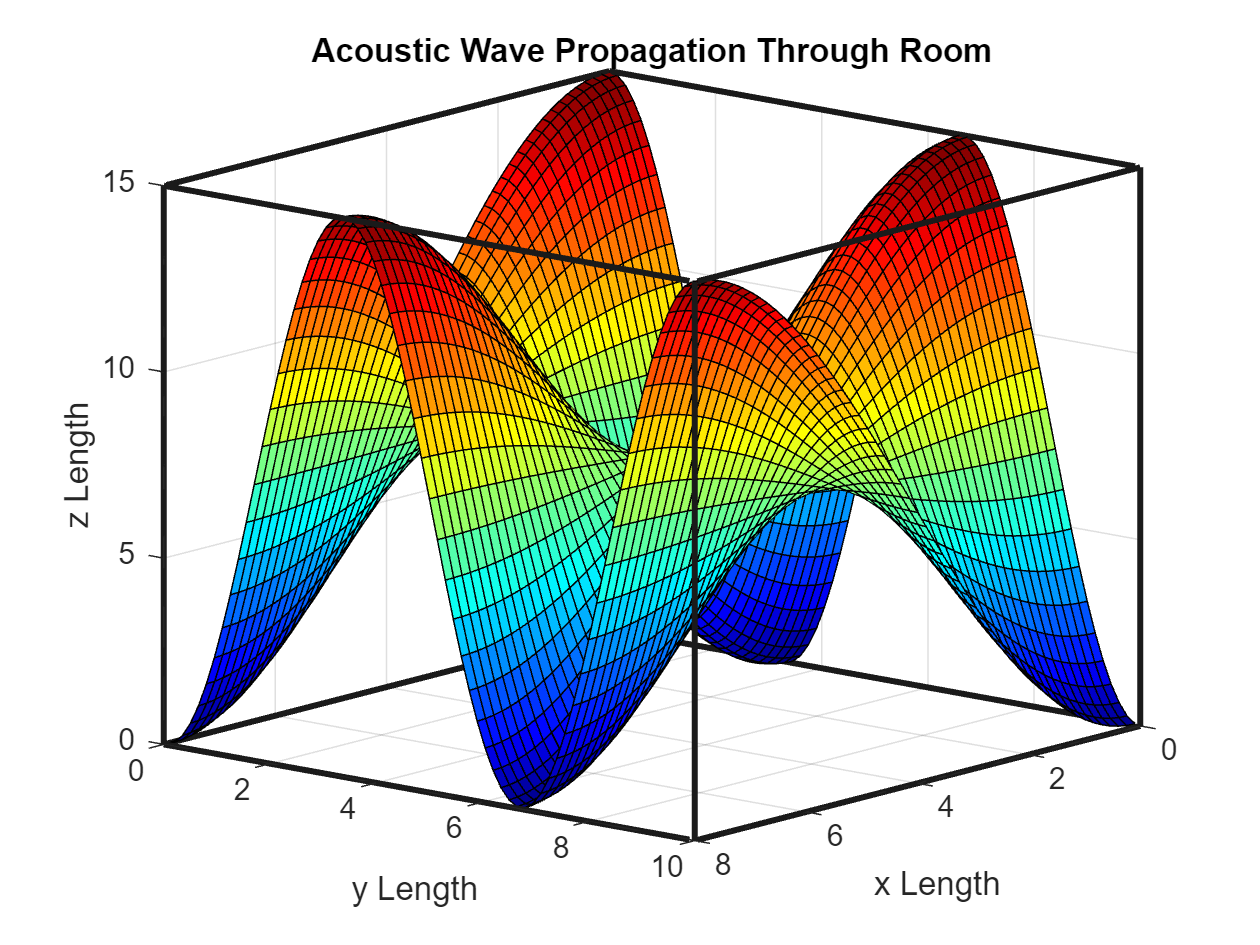

% --Setup
    clear; clc; format compact; close all; warning off;

% --Parameters
    l = 1;
    m = 3;
    n = 2;
    x_location = 0;   % x location of source
    y_location = 0;   % y location of source
     A = 1;          % Complex amplitude
    Lx = 8;         % meters
    Ly = 10;         % meters
    Lz = 15;         % meters
    resolution = max([Lz, Ly, Lx]/100);  % meters
   

    x = 0:resolution:Lx;
    y = 0:resolution:Ly;
    z = 0:resolution:Lz;
    wall = ones(1,length(x));
    wall_y = ones(1,length(y));
    wall_z = ones(1,length(z));

% --Plot room
    plot3(x, Ly.*wall, Lz.*wall, 'Color', [0.1 0.1 0.1], 'LineWidth', 2)
        hold on
        grid on
    plot3(x, 0.*wall, 0.*wall, 'Color', [0.1 0.1 0.1], 'LineWidth', 2)
    plot3(x, Ly.*wall, 0.*wall, 'Color', [0.1 0.1 0.1], 'LineWidth', 2)
    plot3(x, 0.*wall, Lz.*wall, 'Color', [0.1 0.1 0.1], 'LineWidth', 2)

    plot3(0.*wall_y, y, 0.*wall_y, 'Color', [0.1 0.1 0.1], 'LineWidth', 2)
    plot3(Lx.*wall_y, y, 0.*wall_y, 'Color', [0.1 0.1 0.1], 'LineWidth', 2)
    plot3(Lx.*wall_y, y, Lz.*wall_y, 'Color', [0.1 0.1 0.1], 'LineWidth', 2)
    plot3(0.*wall_y, y, Lz.*wall_y, 'Color', [0.1 0.1 0.1], 'LineWidth', 2)

    plot3(0.*wall_z, 0.*wall_z, z, 'Color', [0.1 0.1 0.1], 'LineWidth', 2)
    plot3(Lx.*wall_z, 0.*wall_z, z, 'Color', [0.1 0.1 0.1], 'LineWidth', 2)
    plot3(0.*wall_z, Ly.*wall_z, z, 'Color', [0.1 0.1 0.1], 'LineWidth', 2)
    plot3(Lx.*wall_z, Ly.*wall_z, z, 'Color', [0.1 0.1 0.1], 'LineWidth', 2)
        xlabel('x Length')
        ylabel('y Length')
        zlabel('z Length')  
        view([130 15])
        title("Acoustic Wave Propagation Through Room")

% --K definitions
    kx = l*pi/Lx;
    ky = m*pi/Ly;
    kz = n*pi/Lz;

% --Meshgrid
    [X, Y, Z] = meshgrid(x,y,z);
    Px = A.*cos(kx.*X - x_location).*A.*cos(ky.*Y - y_location);
    Px = Px(:,:,1);
    min_Px = min(min(Px));
    max_Px = max(max(Px));
    Px = Lz.*(Px - min_Px) ./ (max_Px*2);
    surf(X(:,:,1),Y(:,:,1),Px)
        colormap('jet')